clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',8);
set(0,'DefaultTextFontsize',8);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');


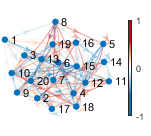

addpath('./esn/');

%% load reservoir
Nrlist = [10 20 50 500];
SRlist = [1.7 1.1 1.1 1.1];

k = 1;

Nr = Nrlist(k);
SR = SRlist(k);

No = 39;

filename = ['esnseed\esn_Nr' num2str(Nr) 'SR' num2str(SR*10) 'No' num2str(No) '.mat'];
load(filename, 'esn');

p = abs(esn.Wr);
[m, n] = find(p~=0);
v = [];
for i = 1:size(m,1)
    v(i) = esn.Wr(m(i),n(i));
end

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',[5,5,4,3.6]);
set(gca,'Position', [-0.08 0.05 0.92 0.9]);
set(gcf,'Visible','on');

g = digraph(m,n,v);
pp = plot(g);
axis off;
pp.EdgeCData = v;
pp.ArrowSize = 6;
cb = colorbar();
cb.Limits = [-1 1];
cb.Ticks = [-1 0 1];
colormap(flipud(othercolor('RdBu5')));
cb.Position = [0.85, 0.15, 0.025, 0.7];

function c = bluegrayred(m)

if nargin < 1
    m = size(get(gcf,'colormap'),1); 
end

% r = 0.3*(0:m-1)'/max(m-1,1);
% r = 0.7 + r;
% g = 0.7*(0:m-1)'/max(m-1,1);
% g = flipud(g);
% b = g;

% 0,0,1 - 0.5,0.5,0.5 - 1,0,0

if (mod(m,2) == 0)
    m1 = m*0.5;
    r = 0.5*(0:m1-1)'/max(m1-1,1);
    g = r;
    r = [r; 0.5+r];
    g = [g; flipud(g)];
    b = flipud(r);
else
    m1 = floor(m*0.5);
    r = 0.5*(0:m1-1)'/max(m1,1);
    g = r;
    r = [r; 0.5; 0.5+r];
    g = [g; 0.5; flipud(g)];
    b = flipud(r);
end

c = [r g b]; 
end